addpath './semi-parameters'
warning off; clear; clc; 
config_LSTM;

### 计算回归矩阵

P = transform_parameters(opt_x);
friction_parameters = zeros(7, 5);
friction_parameters_tandard = zeros(7, 5);
for joint = Joint(1, 1) : Joint(end, 1)
    friction_parameters(joint, :) = [[opt_x(71 + (joint - 1) * 4 : 74 + (joint - 1) * 4)]', [opt_x(99 + (joint - 1))]];
end

load('data/filtering_data_no_downsampling.mat');
q_filt_0 = q_filt;
qd_filt_0 = qd_filt;
qdd_filt_0 = qdd_filt;
t_filt_0 = t_filt;

load('data/filted_No1_excitation_trajectory.mat');
q_filt_1 = q_filt;
qd_filt_1 = qd_filt;
qdd_filt_1 = qdd_filt;
t_filt_1 = t_filt;

load('data/filted_No2_excitation_trajectory.mat');
q_filt_2 = q_filt;
qd_filt_2 = qd_filt;
qdd_filt_2 = qdd_filt;
t_filt_2 = t_filt;

load('data/filted_No3_excitation_trajectory.mat');
q_filt_3 = q_filt;
qd_filt_3 = qd_filt;
qdd_filt_3 = qdd_filt;
t_filt_3 = t_filt;

load('data/filted_No4_excitation_trajectory.mat');
q_filt_4 = q_filt;
qd_filt_4 = qd_filt;
qdd_filt_4 = qdd_filt;
t_filt_4 = t_filt;

load('data/filted_No5_excitation_trajectory.mat');
q_filt_5 = q_filt;
qd_filt_5 = qd_filt;
qdd_filt_5 = qdd_filt;
t_filt_5 = t_filt;

q_filt = [q_filt_0; q_filt_1; q_filt_2; q_filt_3; q_filt_4; q_filt_5];
qd_filt = [qd_filt_0; qd_filt_1; qd_filt_2; qd_filt_3; qd_filt_4; qd_filt_5];
qdd_filt = [qdd_filt_0; qdd_filt_1; qdd_filt_2; qdd_filt_3; qdd_filt_4; qdd_filt_5];
t_filt = [t_filt_0; t_filt_1; t_filt_2; t_filt_3; t_filt_4; t_filt_5];

clearvars q q_filt_0 q_filt_1 q_filt_2 q_filt_3 q_filt_4 q_filt_5 ...
          qd qd_filt_0 qd_filt_1 qd_filt_2 qd_filt_3 qd_filt_4 qd_filt_5 ...
          qdd qdd_filt_0 qdd_filt_1 qdd_filt_2 qdd_filt_3 qdd_filt_4 qdd_filt_5 ...
          t_filt_0 t_filt_1 t_filt_2 t_filt_3 t_filt_4 t_filt_5;

g = 9.80665;
[n_sample, ~] = size(q_filt);
T = zeros(n_sample, 7);
T_idy = zeros(n_sample, 7);

for k = 1 : n_sample
    q = q_filt(k, :);
    qd = qd_filt(k, :);
    qdd = qdd_filt(k, :);
    T(k, :) = t_filt(k, :);
    ww = compute_regression_matrix(q, qd, qdd, 0);

    T_idy(k,:) = ww * P';

    for i = 1 : 7
        T_idy(k, i) = T_idy(k, i) + compute_Stribeck_friction(qd(1, i), friction_parameters(i, :), gamma);
    end
end

### 第一步：制作数据集

num_sample_point = size(q_filt, 1);
database = zeros(num_factors * size(Joint, 1), num_sample_point);
T_error = t_filt - T_idy;

for frame = 1 : num_sample_point
   database(:, frame) = [q_filt(frame, :)'; qd_filt(frame, :)'; qdd_filt(frame, :)'; T_error(frame, :)'];
end


### 第二步：划分数据集 & 转换格式

% 划分数据集
split = floor(num_sample_point * train_percent);
INPUT_TRAIN = database(1 : (num_factors - 1) * size(Joint, 1), 1 : split);
output_train = database((num_factors - 1) * size(Joint, 1) + 1 : end, 1 : split);
INPUT_TEST = database(1 : (num_factors - 1) * size(Joint, 1), split + 1 : end);
output_test = database((num_factors - 1) * size(Joint, 1) + 1 : end, split + 1 : end);

% 格式转换
input_train = cell(1, size(INPUT_TRAIN, 2));
input_test = cell(1, size(INPUT_TEST, 2));

for i = 1 : size(INPUT_TRAIN, 2)
    input_train{1, i} = INPUT_TRAIN(:, i);
end

for i = 1 : size(INPUT_TEST, 2)
    input_test{1, i} = INPUT_TEST(:, i);
end


## 加载神经网络辨识力矩

load('data/Semi_parameters/LSTM_net_backup.mat');
t_sim1 = predict(net, input_train);
t_sim2 = predict(net, input_test);
t_sim = double([t_sim1; t_sim2]);

Tsemi_idy = T_idy + t_sim; 

## 单次辨识：第一步-加载参数

addpath '.\utils';    
addpath '.\Stribeck';
addpath '.\traditional';   
addpath '.\traditional\verify\';

load('data\parameters_identified\Stribeck\parameters_Stribeck_2024-04-10_21-39.mat');   param_Stribeck = opt_x;

[n_sample, ~] = size(q_filt);
n_parameters = 43;

## 计算力矩

ww = zeros(n_sample * 7, n_parameters);

for k = 1 : n_sample
    q = q_filt(k, :);
    qd = qd_filt(k, :);
    qdd = qdd_filt(k, :);

    start_row = 1 + (k - 1) * 7;
    end_row = k * 7;

    if n_parameters == 43 
        flag = 0;
    else
        flag = 1;
    end

    ww(start_row : end_row, :) = compute_regression_matrix(q, qd, qdd, flag);
end

n_parameters = 105;
T_idy_Stribeck = compute_identified_torque_with_Stribeck_model(param_Stribeck, qd_filt);
T_idy_Stribeck = reshape(T_idy_Stribeck, 7, []);    T_idy_Stribeck = T_idy_Stribeck';

## 第二步：建立神经网络并进行训练

% 建立数据集
T_error_Stribeck = t_filt - T_idy_Stribeck;
database = zeros(num_factors * size(Joint, 1), num_sample_point);

for frame = 1 : num_sample_point
   database(:, frame) = [q_filt(frame, :)'; qd_filt(frame, :)'; qdd_filt(frame, :)'; T_error(frame, :)'];
end

% 划分数据集
split = floor(num_sample_point * train_percent);
INPUT_TRAIN = database(1 : (num_factors - 1) * size(Joint, 1), 1 : split);
output_train = database((num_factors - 1) * size(Joint, 1) + 1 : end, 1 : split);
INPUT_TEST = database(1 : (num_factors - 1) * size(Joint, 1), split + 1 : end);
output_test = database((num_factors - 1) * size(Joint, 1) + 1 : end, split + 1 : end);

% 格式转换
input_train = cell(1, size(INPUT_TRAIN, 2));
input_test = cell(1, size(INPUT_TEST, 2));

for i = 1 : size(INPUT_TRAIN, 2)
    input_train{1, i} = INPUT_TRAIN(:, i);
end

for i = 1 : size(INPUT_TEST, 2)
    input_test{1, i} = INPUT_TEST(:, i);
end


### 定义LSTM神经网络

layers = [
    sequenceInputLayer((num_factors - 1) * size(Joint, 1))        % 建立输入层
    
    lstmLayer(32, 'OutputMode', 'last')                           % LSTM层
    reluLayer                                                     % Relu激活层

    lstmLayer(16, 'OutputMode', 'last')                           % LSTM层
    reluLayer                                                     % Relu激活层

    lstmLayer(8, 'OutputMode', 'last')                            % LSTM层
    reluLayer                                                     % Relu激活层

    fullyConnectedLayer(7)                                        % 全连接层
    regressionLayer                                               % 回归层
    ];

### LSTM参数设置

options = trainingOptions('adam', ...            % Adam 梯度下降算法
    'MiniBatchSize', BatchSize, ...              % 批大小
    'MaxEpochs', Epochs, ...                     % 最大迭代次数
    'InitialLearnRate', 0.05, ...                % 初始学习率
    'LearnRateSchedule', 'piecewise', ...        % 学习率下降
    'LearnRateDropFactor', 0.5, ...              % 学习率下降因子
    'LearnRateDropPeriod', Epochs * 0.4, ...     % 经过X次训练后，学习率为InitialLearnRate * LearnRateDropFactor
    'Shuffle', 'every-epoch', ...                % 每次训练后训练打乱数据
    'Plots', 'training-progress', ...            % 画出曲线
    'Verbose', false);

### 第四步：训练神经网络

net = trainNetwork(input_train, output_train', layers, options);
save('data\Semi_parameters\LSTM_net_Stribeck-20250113.mat', 'net');

## 计算力矩 & 验证

load('data/Semi_parameters/LSTM_net_Stribeck-20250113.mat');
t_sim1 = predict(net, input_train);
t_sim2 = predict(net, input_test);
t_sim = double([t_sim1; t_sim2]);

Tsemi_idy_Stribeck = T_idy_Stribeck + t_sim; 


## 画图

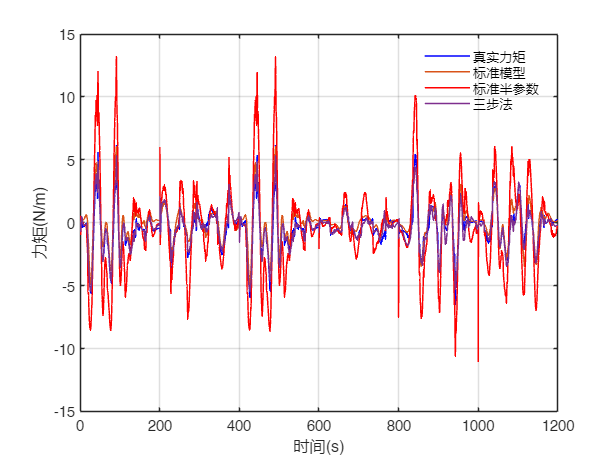

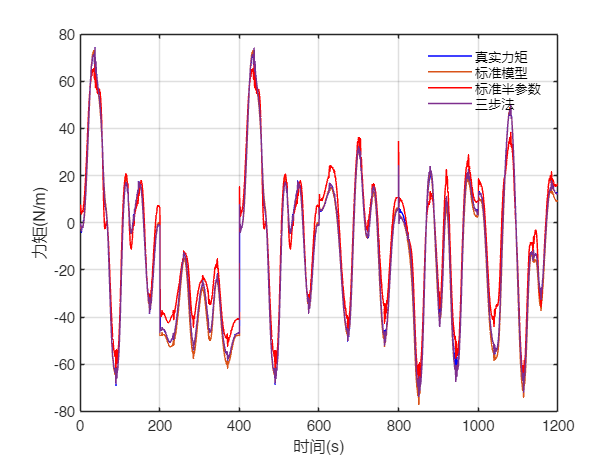

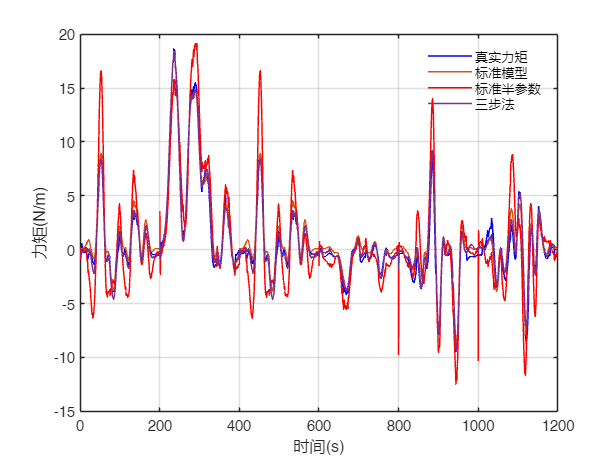

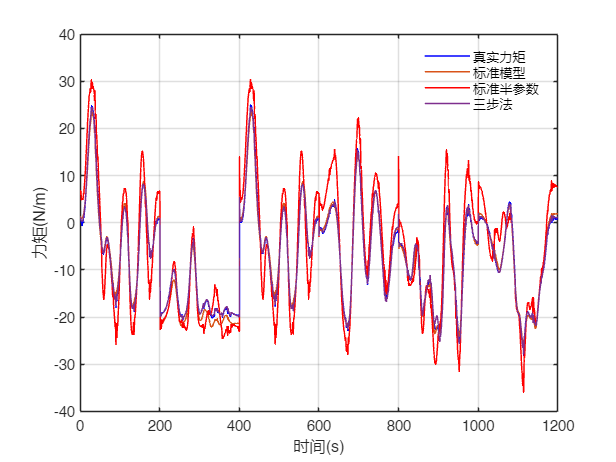

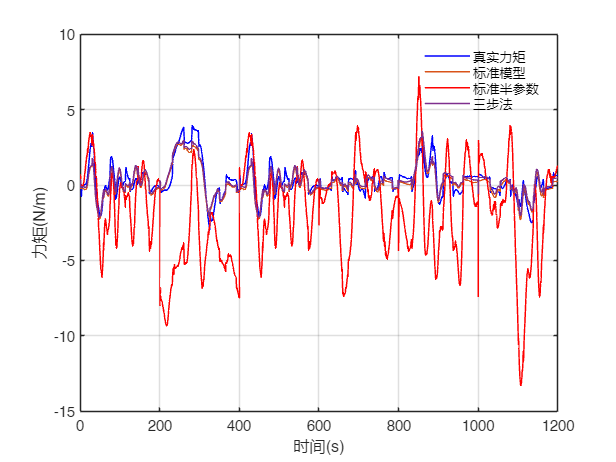

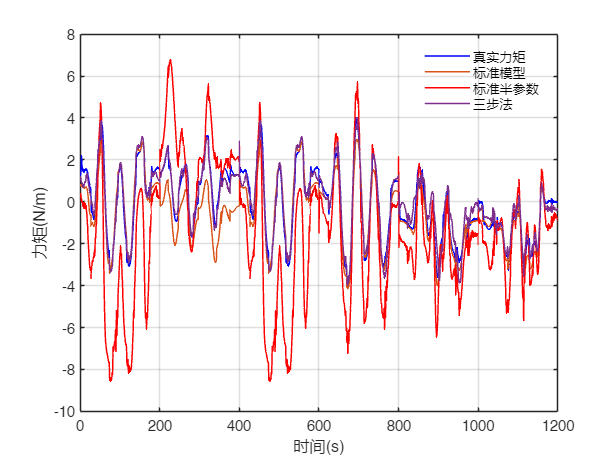

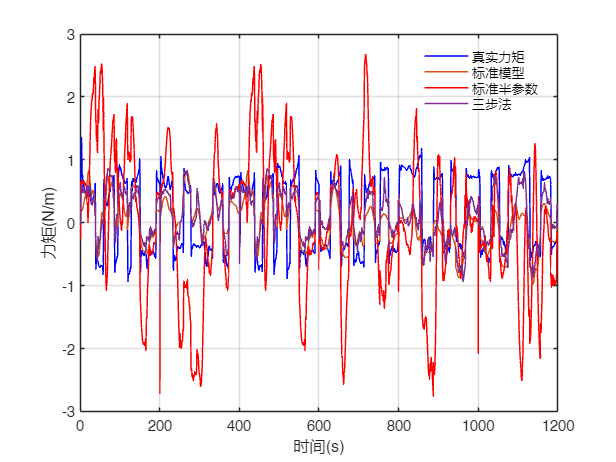

traj_Ts = 0.01;

t = linspace(0, n_sample - 1, n_sample) * traj_Ts;

for i = 1 : 7
    figure;
    plot(t, T(:, i), 'b', 'LineWidth', 1.0); hold on;
    plot(t, T_idy(:, i), 'LineWidth', 1.0);
    plot(t, Tsemi_idy_Stribeck(:, i), 'r', 'LineWidth', 1.0);
    plot(t, Tsemi_idy(:, i), 'LineWidth', 1.0);
    hold off;
    ylabel('力矩(N/m)');
    xlabel('时间(s)');
    xlim([0, 1200]);
    legend('真实力矩', '标准模型', '标准半参数', '三步法');
    legend('boxoff');
    grid on;
    % title(['No.', num2str(i), 'joint torque']);
end

## 计算RMSE值

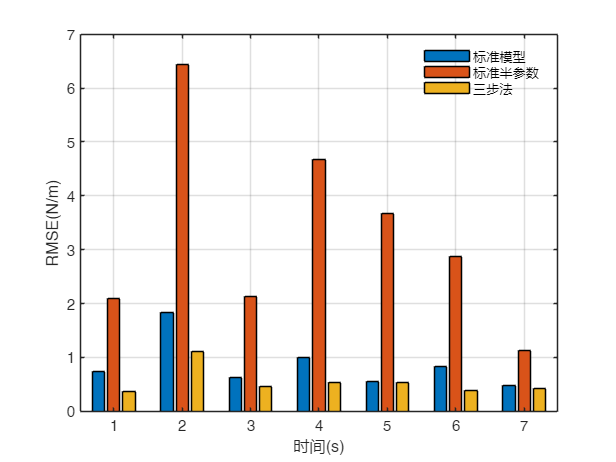

figure;
bar([rmse(T(1:split, :), T_idy(1:split, :), 1); ...
    rmse(T(1:split, :), Tsemi_idy_Stribeck(1:split, :), 1); ...
    rmse(T(1:split, :), Tsemi_idy(1:split, :), 1)]');
legend('标准模型', '标准半参数', '三步法');
ylabel('RMSE(N/m)');
xlabel('时间(s)');
legend('boxoff');
grid on;

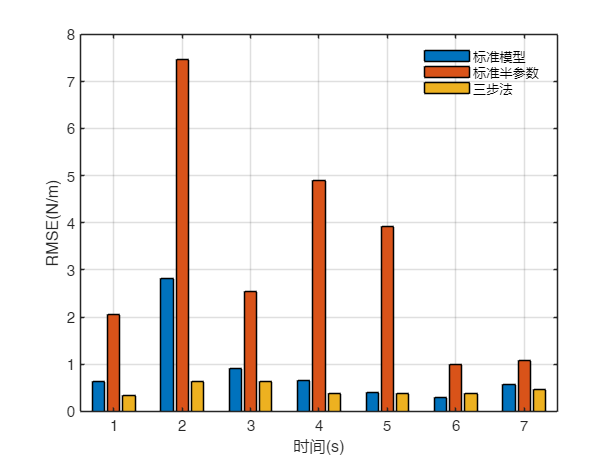

% title(['RMSE of different identification strategy in training set']);
figure;
bar([rmse(T(split + 1 : end, :), T_idy(split + 1 : end, :), 1); ...
    rmse(T(split + 1 : end, :), Tsemi_idy_Stribeck(split + 1 : end, :), 1); ...
    rmse(T(split + 1 : end, :), Tsemi_idy(split + 1 : end, :), 1)]');
legend('标准模型', '标准半参数', '三步法');
ylabel('RMSE(N/m)');
xlabel('时间(s)');
legend('boxoff');
grid on;

% title(['RMSE of different identification strategy in validation set']);

[rmse(T(1:split, :), T_idy(1:split, :), 1); ...
 rmse(T(1:split, :), Tsemi_idy_Stribeck(1:split, :), 1); ...
 rmse(T(1:split, :), Tsemi_idy(1:split, :), 1)]

ans =     0.7352    1.8423    0.6278    0.9959    0.5529    0.8398    0.4724
    2.1006    6.4276    2.1392    4.6807    3.6771    2.8680    1.1368
    0.3625    1.1025    0.4634    0.5432    0.5338    0.3903    0.4233



[rmse(T(split + 1 : end, :), T_idy(split + 1 : end, :), 1); ...
 rmse(T(split + 1 : end, :), Tsemi_idy_Stribeck(split + 1 : end, :), 1); ...
 rmse(T(split + 1 : end, :), Tsemi_idy(split + 1 : end, :), 1)]

ans =     0.6421    2.8177    0.9088    0.6643    0.4045    0.2859    0.5663
    2.0550    7.4613    2.5334    4.8983    3.9200    1.0039    1.0706
    0.3459    0.6255    0.6432    0.3888    0.3856    0.3796    0.4560
